# MATLAB Tutorial 6. PID Controller Design

## 1. 문제정의와 기본 근궤적 그리기

clc; clear
% 개루프 전달함수 G(s)H(s)
s = tf('s');
otf = 1/((s+3)*(s+5)*(s+10))

otf =
 
              1
  -------------------------
  s^3 + 18 s^2 + 95 s + 150
 
연속시간 전달 함수입니다.



% 최대초과 비율
os = 0.20;
% 최대첨두값시간
tp = 0.3;
% 근궤적 그리기
rlocus(otf)
hold on

## 2. 목표 극점 설계

[zeta, theta] = draw_overshoot_line(os, 'b--');

%OS=0.2, zeta=0.4559, theta=62.874(deg)


w_d = draw_peak_time_line(tp, 'r--');

w_d = 10.4720

Tp=0.3000, imag(pole)=10.4720


wn = w_d/sqrt(1-zeta^2);
pole_real = -zeta*wn;
pole_imag = w_d;
target_pole = pole_real + 1i*pole_imag;
fprintf('최대초과와 정정시간을 만족하는 극점의 위치 s = %.4f + j%.4f\n', ...
        pole_real, pole_imag)

최대초과와 정정시간을 만족하는 극점의 위치 s = -5.3648 + j10.4720


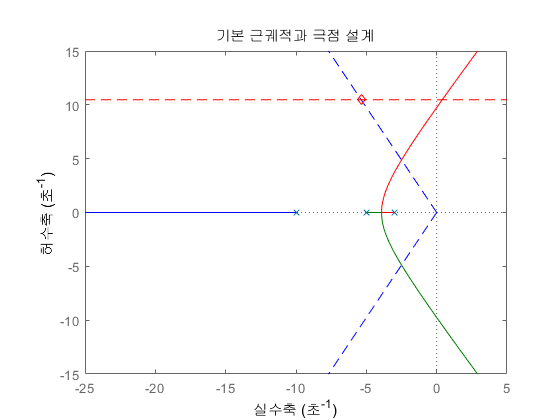

plot(pole_real, pole_imag, 'rd')
hold off
axis([-25 5 -15 15])
title('기본 근궤적과 극점 설계')

## 3. PD 제어기의 영점 설계

zero_pd = design_pd_controller(otf, target_pole);


>>>>> 근궤적이 목표 극점을 지나게 하는 PD 제어기 설계 
목표 극점에서의 개루프 전달함수 위상 계산
극점의 위상 angle(s - (-10.000 + j0.000)) = 66.124(deg)
극점의 위상 angle(s - (-5.000 + j0.000)) = 91.995(deg)
극점의 위상 angle(s - (-3.000 + j0.000)) = 102.725(deg)
극점 s = -5.365 + j10.472 에서 G(s)의 위상 = -260.8(deg) = -4.553(rad)
PD 제어기가 가져야할 위상 = 3.142 - (-4.553) = 1.4110(rad) = 80.845(deg)
PD 제어기의 영점 위치 = -7.0525


% PD 제어기를 반영한 근궤적
otf_pd = otf * (s - zero_pd)

otf_pd =
 
          s + 7.053
  -------------------------
  s^3 + 18 s^2 + 95 s + 150
 
연속시간 전달 함수입니다.



K = -1/evalfr(otf_pd, target_pole);
K = real(K);
fprintf("PD 제어기 적용 후 target pole에서의 상수 이득 K=%1.4f\n", K)

PD 제어기 적용 후 target pole에서의 상수 이득 K=121.4518


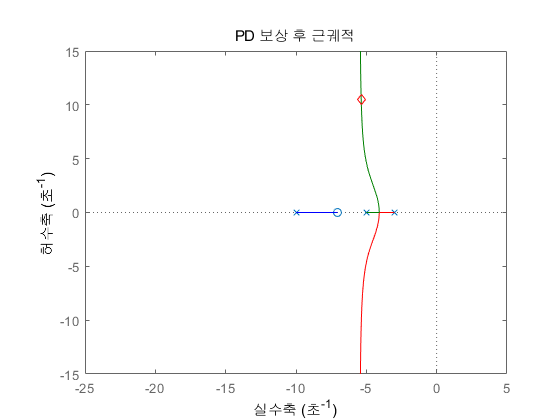

rlocus(otf_pd)
hold on
plot(real(target_pole), imag(target_pole), 'rd')
hold off
title('PD 보상 후 근궤적')
axis([-25 5 -15 15])

% 보정된 시스템의 성능 확인
tf_total = feedback(K*otf_pd, 1)

tf_total =
 
         121.5 s + 856.5
  -----------------------------
  s^3 + 18 s^2 + 216.5 s + 1007
 
연속시간 전달 함수입니다.



% 성능에 약간의 오차 있음
S = stepinfo(tf_total)

S = 다음 필드를 포함한 struct :
        RiseTime: 0.1298
    SettlingTime: 0.7078
     SettlingMin: 0.7725
     SettlingMax: 1.0312
       Overshoot: 21.1774
      Undershoot: 0
            Peak: 1.0312
        PeakTime: 0.3004


## 4. PI 제어기 설계

zero_pi = -0.01;
fprintf('PI 제어기의 영점 위치 선택: %.1f\n', zero_pi)

PI 제어기의 영점 위치 선택: -0.0


% PID 제어기를 반영한 근궤적
otf_pid = otf_pd * (s - zero_pi) / s

otf_pid =
 
     s^2 + 7.063 s + 0.07053
  -----------------------------
  s^4 + 18 s^3 + 95 s^2 + 150 s
 
연속시간 전달 함수입니다.



rlocus(otf_pid)
hold on
plot(real(target_pole), imag(target_pole), 'rd')

fprintf('target pole에서의 상수이득:')

target pole에서의 상수이득:

% PI 제어기로 인해 점근선이 정확히 target pole을 지나지 않아서 실수가 아닌 
% 복소수가 나오고 크기는 PD제어기에서 계산한 것과 크게 다르지 않음
K = -1/evalfr(otf_pid, target_pole)

K = 1.2150e+02 + 9.1938e-02i

% K 값은 양의 실수여야 하므로 실수부만 사용함
K = real(K)

K = 121.4988

mark_closed_pole(K*otf_pid)

PID 제어기 반영하여 전체 시스템 T(s)의 극점 계산


final_poles =   -5.3604 +10.4721i
  -5.3604 -10.4721i
  -7.2706 + 0.0000i
  -0.0085 + 0.0000i


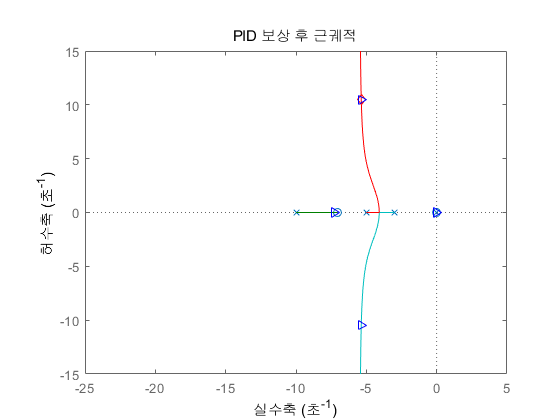

hold off
axis([-25 5 -15 15])
title('PID 보상 후 근궤적')

## 5. 제어기 성능 확인

% 보정된 시스템의 성능 확인
tf_total = feedback(K*otf_pid, 1)

tf_total =
 
         121.5 s^2 + 858.1 s + 8.569
  -----------------------------------------
  s^4 + 18 s^3 + 216.5 s^2 + 1008 s + 8.569
 
연속시간 전달 함수입니다.



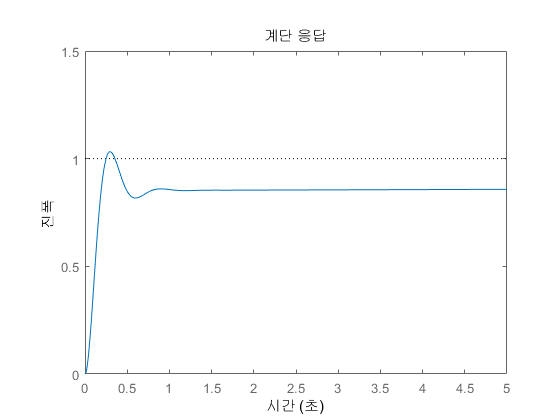

step(tf_total, 0:0.01:5)
axis([0 5 0 1.5])

% '정상상태 값'이란 기준이 1이 돼버려서 이상한 성능값이 나옴
S = stepinfo(tf_total)

S = 다음 필드를 포함한 struct :
        RiseTime: 0.1618
    SettlingTime: 235.4648
     SettlingMin: 0.8173
     SettlingMax: 1.0321
       Overshoot: 3.2132
      Undershoot: 0
            Peak: 1.0321
        PeakTime: 0.3028


function [zeta, theta] = draw_overshoot_line(os, style)
    zeta = sqrt(log(os)^2 / (log(os)^2 + pi^2));
    theta = acos(zeta);
    fprintf('%%OS=%.1f, zeta=%.4f, theta=%.3f(deg)\n', os, zeta, rad2deg(theta))
    plot([0 -100*cos(theta)], [0  100*sin(theta)], style)
    plot([0 -100*cos(theta)], [0 -100*sin(theta)], style)
end

function sigma_d = draw_settle_time_line(ts, style)
    sigma_d = 4/ts;
    fprintf('Ts=%.4f, |real(pole)|=%.4f\n', ts, sigma_d)
    plot([-sigma_d, -sigma_d], [-100, 100], style)
end

function w_d = draw_peak_time_line(tp, style)
    w_d = pi/tp
    fprintf('Tp=%.4f, imag(pole)=%.4f\n', tp, w_d)
    plot([-100, 100], [w_d, w_d], style)
end

function mark_closed_pole(otf)
    % 제어기 대입시 target_pole이 극점으로 나오는지 검증
    tf_total = feedback(otf, 1);
    disp('PID 제어기 반영하여 전체 시스템 T(s)의 극점 계산')
    final_poles = pole(tf_total)
    for p=final_poles
        plot(real(p), imag(p), 'b>')
    end
end

function zero_pd = design_pd_controller(otf, target_pole)
    fprintf('\n>>>>> 근궤적이 목표 극점을 지나게 하는 PD 제어기 설계 \n')
    disp('목표 극점에서의 개루프 전달함수 위상 계산')
    phase_G = 0;
    zero_otf = zero(otf);
    pole_otf = pole(otf);
    if ~isempty(zero_otf)
        for i=1:size(zeros_otf,1)
            vector = target_pole - zero_otf(i);
            zero_phase = atan2(imag(vector), real(vector));
            phase_G = phase_G + zero_phase;
            fprintf('영점의 위상 angle(s - (%.3f + j%.3f)) = %.3f rad\n', ...
                    real(zero_otf(i)), imag(zero_otf(i)), zero_phase)
        end
    end
    for i=1:size(pole_otf,1)
        vector = target_pole - pole_otf(i);
        pole_phase = atan2(imag(vector), real(vector));
        phase_G = phase_G - pole_phase;
        fprintf('극점의 위상 angle(s - (%.3f + j%.3f)) = %.3f(deg)\n', ...
                real(pole_otf(i)), imag(pole_otf(i)), rad2deg(pole_phase))
    end
    fprintf('극점 s = %.3f + j%.3f 에서 G(s)의 위상 = %.1f(deg) = %.3f(rad)\n', ...
            real(target_pole), imag(target_pole), rad2deg(phase_G), phase_G)
    phase_PD = -pi - phase_G;
    fprintf('PD 제어기가 가져야할 위상 = %.3f - (%.3f) = %.4f(rad) = %.3f(deg)\n', ...
            pi, phase_G, phase_PD, rad2deg(phase_PD))
    zero_pd = real(target_pole) - imag(target_pole)/tan(phase_PD);
    fprintf('PD 제어기의 영점 위치 = %.4f\n', zero_pd)
end